parallel.gpu.enableCUDAForwardCompatibility(true)

ir_len = 128;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

[target, ref] = recorded_samples();

filter_order = ir_len * 2;
n_iter = 3;

% mu = 0.05;
% fxlms = FxLMS(ref, target, panel_ir, filter_order, mu);
% fxlms.gpu = false;

% [pred, mses] = fxlms.learn(n_iter, true);

% figure
% plot(mses);

lamda = 0.999;
cov_scale = 0.1

cov_scale = 0.1000

fxrls_small = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);

fxrls_small.gpu = false;

[pred_small, mses_small] = fxrls_small.learn(n_iter, true);

Iteration 1/3
Iteration 2/3
Iteration 3/3


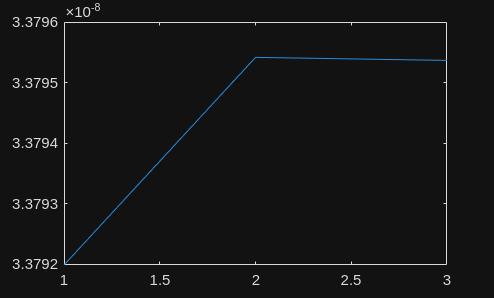

figure
plot(mses_small);

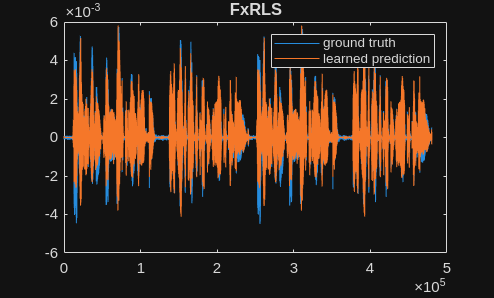

fxrls_small.results_plot()

ir_len = 1024;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

filter_order = ir_len * 2;
n_iter = 2;

fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);
fxrls.gpu = true;

[pred, mses] = fxrls.learn(n_iter, true);

Iteration 1/2
Iteration 2/2


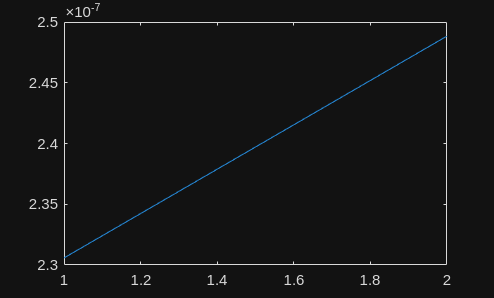

figure
plot(mses);

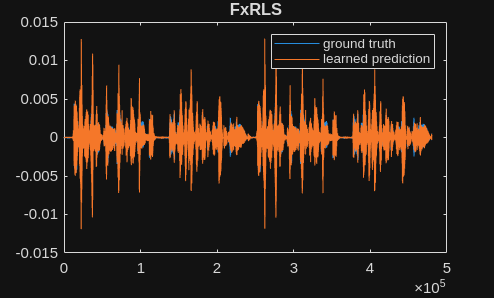

fxrls.results_plot()

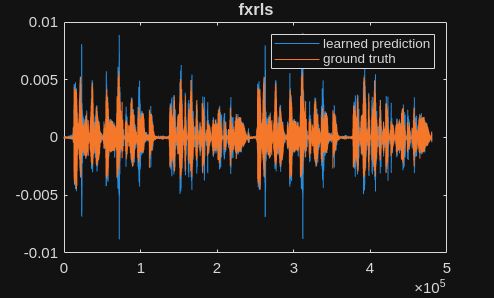

figure
plot(pred)
hold on
plot(target)
legend('learned prediction', 'ground truth')
title('fxrls')

load('rls workspace.mat')

ir_lens = [128, 256, 512, 1024];

ir_lens =          128         256         512        1024


Iteration 1/1


   3.3550e-08



Iteration 1/1


   5.5359e-08



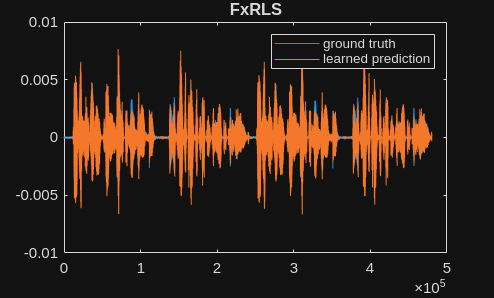

Iteration 1/1


   1.4146e-07



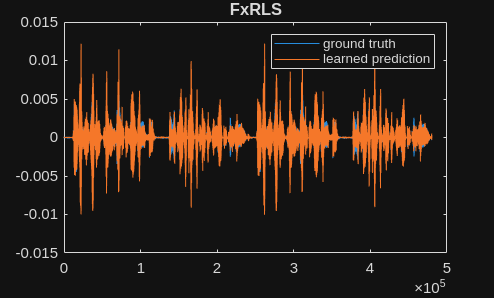

Iteration 1/1


   2.3058e-07



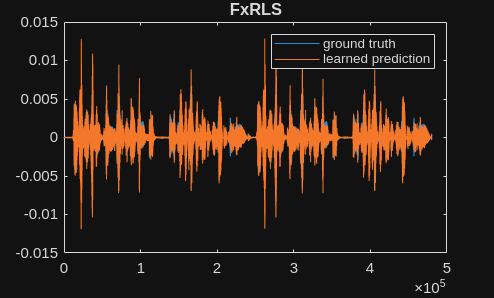

N = length(ir_lens);
mse_lens = zeros(N, 1);
preds = zeros(N, length(target));
parallel.gpu.enableCUDAForwardCompatibility(true)

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;
    panel_ir = clipped_irs(ir_len, source_to_ref_cm);
    filter_order = ir_len * 2;
    n_iter = 1;

    fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);
    fxrls.gpu = ir_len > 257;
    [pred_i, mses_i] = fxrls.learn(n_iter, true);

    mse_lens(i) = mses_i;
    preds(i, :) = pred_i;
    
    disp(mses_i)
    fxrls.results_plot();

end

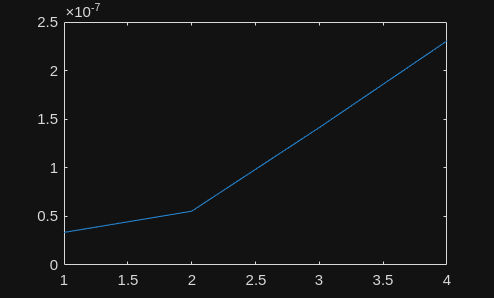

figure
plot(mse_lens)